## Association of clinically significant M**S** with physical exam variables

Here I want to explore the group characteristics of the cohort consisting of subjects with presence MS. One of the motivations for this investigation is to get a sense of how good cardiac auscultation is at predicting MS. First we define the dataset.

Ind = HSdata0.MSGRADE_T72>0;
dataSick    = HSdata0(Ind,:);
dataHealthy = HSdata0(~Ind,:);

What is the **gender** **distribution** of the disease?

mean(dataSick.SEX_T7==1)

ans = 0.2143

sum(dataSick.SEX_T7==1)

ans = 3

mean(dataHealthy.SEX_T7==1)

ans = 0.4615

sum(dataHealthy.SEX_T7==1)

ans = 976

We see that the **males** are far **underrepresented**, but we cannot claim significance as there are too few samples. What about **age**?

mean(dataSick.AGE_T7)

ans = 78.1429

mean(dataHealthy.AGE_T7)

ans = 63.9069

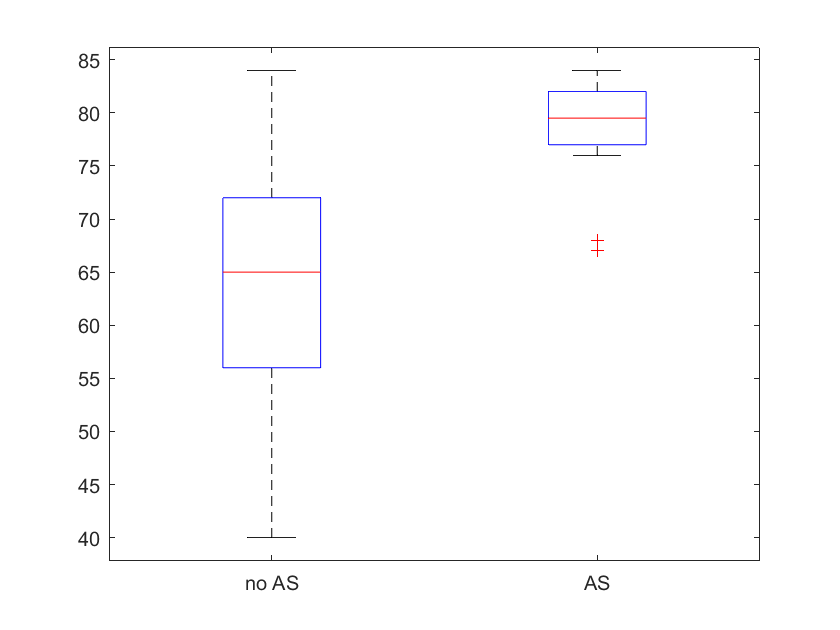

boxplot(HSdata0.AGE_T7,log2cat(Ind,"AS","no AS"));

As expected, MS is **associated** with **old** age, and age is **significant**. Dyspnoe, or laboured **breathing**, is an important risk factor.

mean(dataSick.DYSPNEA_FAST_UPHILL_T7==1,'omitnan')

ans = 0.5000

mean(dataHealthy.DYSPNEA_FAST_UPHILL_T7,'omitnan')

ans = 0.3892

We see that there is a significant difference, **50.0%** vs **38.92%**, a difference of about **11.2%**. Dyspnea is **significant**. Is the "fast uphill" better at separating the two cohorts?

mean(dataSick.DYSPNEA_CALMLY_FLAT_T7==1,'omitnan')

ans = 0.1429

mean(dataHealthy.DYSPNEA_CALMLY_FLAT_T7==1,'omitnan')

ans = 0.0255

mean(dataSick.DYSPNOE_WASHING_DRESSING_T7==1,'omitnan')

ans = 0.1429

mean(dataHealthy.DYSPNOE_WASHING_DRESSING_T7==1,'omitnan')

ans = 0.0307

mean(dataSick.DYSPNOE_REST_T7==1,'omitnan')

ans = 0

mean(dataHealthy.DYSPNOE_REST_T7==1,'omitnan')

ans = 0.0061

We are probably best of using the fast uphill test. Lets have a look at whether or not chest pain predicts AR.

mean(dataSick.CHEST_PAIN_FAST_T7==1,'omitnan')

ans = 0.2143

mean(dataHealthy.CHEST_PAIN_FAST_T7==1,'omitnan')

ans = 0.0875

No big difference. Next let have a look at BMI. It is concievable that fat people are more likely to have AR.

mean(dataSick.BMI_T7,'omitnan')

ans = 27.7714

mean(dataHealthy.BMI_T7,'omitnan')

ans = 27.1781

No difference. What about smoking status?

mean(dataSick.SMOKE_DAILY_Q2_T7==1,'omitnan')

ans = 0.1429

mean(dataHealthy.SMOKE_DAILY_Q2_T7==1,'omitnan')

ans = 0.1163

Higher prevalence of smoking amongst sick people, but not by much. What about blood pressure?

mean(dataSick.HIGH_BLOOD_PRESSURE_T7>=1,'omitnan')

ans = 0.6429

mean(dataHealthy.HIGH_BLOOD_PRESSURE_T7>=1,'omitnan')

ans = 0.3603

And here we have a **strong** predictor, high blood pressure. In the sick AS cohort **56.5%** had high bloodpressure, whereas the healthy cohort had a **35.8%** high bloodpressure. Next we look at Heart attack:

mean(dataSick.HEART_ATTACK_T7>=1,'omitnan')

ans = 0.0714

mean(dataHealthy.HEART_ATTACK_T7>=1,'omitnan')

ans = 0.0657

No surprises there, there is higher prevalence of heart attack in the AS group, **19.6%** vs **6.3%**. I thought it would be more.

mean(dataSick.HEART_FAILURE_T7>=1,'omitnan')

ans = 0

mean(dataHealthy.HEART_FAILURE_T7>=1,'omitnan')

ans = 0.0336

**Same conclusion** as above.

mean(dataSick.COUGH_DAILY_T7>=1,'omitnan')

ans = 0.2857

mean(dataHealthy.COUGH_DAILY_T7>=1,'omitnan')

ans = 0.1660

Coughing is not a strong predictor of AR. 

Next lets have a look at PO2 max, which measures blood oxygen saturation, and how effective the lungs are at pulling O2 from the air.

mean(dataSick.PO2_T72,'omitnan')

ans = 97.7692

mean(dataHealthy.PO2_T72,'omitnan')  

ans = 97.6447

No difference. What about Lung capacity as measured by a spirometry?

mean(dataSick.PULSESPIRO_T72<60,'omitnan')

ans = 0.0714

mean(dataHealthy.PULSESPIRO_T72<60,'omitnan') 

ans = 0.3362

A significant group difference. The MS group had a 7**.1%** prevalence of scoring less than 60 on the test, whereas for the healthy group the number was only **33.62%**. Finally, for good measure, we look at the predictive value of maximum murmur grade for predicting AR.

mean(dataSick.maxMeanMurGrade>=2,'omitnan')

ans = 0.9286

mean(dataHealthy.maxMeanMurGrade>=2,'omitnan') 

ans = 0.1007

risk of murmur grade >=2 is **92.9%** for the sick group, and **10%** for the healthy group. **Murmur grade is higly predictive of MS**.

### conclusions:

Age, sex, dyspnea fast upphill, high bloodpressure, chest pain, pulse spiro, and murmur grade are significant predictors of significant AR. Let us throw them all into a regression model, but first we have to see how much data is available to model.

data = HSdata0;
Inan = isnan(data.SEX_T7)+isnan(data.AGE_T7)+isnan(data.DYSPNEA_FAST_UPHILL_T7)+...
    isnan(data.HIGH_BLOOD_PRESSURE_T7) + isnan(data.PULSESPIRO_T72) +...
    isnan(data.CHEST_PAIN_FAST_T7) + isnan(data.ASGRADE_T72);
Inan = (Inan>=1);
sum(Inan)

ans = 231

we loose 231 samples.  Will exclusion of the nan entries bias our findings?

mean(data.ASGRADE_T72(~Inan)>0)

ans = 0.0211

mean(data.ASGRADE_T72>0)

ans = 0.0216

sum(~Inan)

ans = 1898

 We have 0.1% increase in prevalence of significant AS, which we conclude to be **insiginificant source of bias**. Now we **model**.

dataMdl = data(~Inan,:);
ASsig = table(dataMdl.MSGRADE_T72>0,'VariableNames',{'MSsig'});
dataMdl = [dataMdl, ASsig];

dataMdl.SEX_T7 = categorical(dataMdl.SEX_T7);
dataMdl.DYSPNEA_FAST_UPHILL_T7 = categorical(dataMdl.DYSPNEA_FAST_UPHILL_T7);
dataMdl.HIGH_BLOOD_PRESSURE_T7 = categorical(dataMdl.HIGH_BLOOD_PRESSURE_T7>0);
dataMdl.CHEST_PAIN_FAST_T7     = categorical(dataMdl.CHEST_PAIN_FAST_T7);

formula = strcat('MSsig ~ AGE_T7 + SEX_T7 + HIGH_BLOOD_PRESSURE_T7 +',...
     'DYSPNEA_FAST_UPHILL_T7 + CHEST_PAIN_FAST_T7 + PULSESPIRO_T72')

formula = 'MSsig ~ AGE_T7 + SEX_T7 + HIGH_BLOOD_PRESSURE_T7 +DYSPNEA_FAST_UPHILL_T7 + CHEST_PAIN_FAST_T7 + PULSESPIRO_T72'

glm = fitglm(dataMdl,formula,'distr','binomial')

glm = Generalized linear regression model:
    logit(MSsig) ~ 1 + AGE_T7 + SEX_T7 + HIGH_BLOOD_PRESSURE_T7 + CHEST_PAIN_FAST_T7 + DYSPNEA_FAST_UPHILL_T7 + PULSESPIRO_T72
    Distribution = Binomial

Estimated Coefficients:
                                   Estimate       SE        tStat        pValue  
                                   ________    ________    ________    __________

    (Intercept)                     -26.535      5.7053     -4.6509    3.3055e-06
    AGE_T7                          0.24066    0.066236      3.6334    0.00027973
    SEX_T7_1                        -0.6435     0.70907    -0.90752       0.36413
    HIGH_BLOOD_PRESSURE_T7_true     0.79633     0.71956      1.1067       0.26843
    CHEST_PAIN_FAST_T7_1           -0.23716     0.85015    -0.2

Get **performance curve** for prediction of significant MS:

glm.predict

ans =     0.0011
    0.0051
    0.0004
    0.0019
    0.0009
    0.0005
    0.0077
    0.0144
    0.0003
    0.0004


[X,Y,T,AUC] = perfcurve(dataMdl.MSsig, glm.predict, true)

X =          0
    0.0005
    0.0011
    0.0011
    0.0011
    0.0016
    0.0021
    0.0026
    0.0032
    0.0037


Y =          0
         0
         0
    0.1000
    0.2000
    0.2000
    0.2000
    0.2000
    0.2000
    0.2000


T =     0.1930
    0.1930
    0.1717
    0.1676
    0.1569
    0.1407
    0.1267
    0.1195
    0.1146
    0.1145


AUC = 0.9128

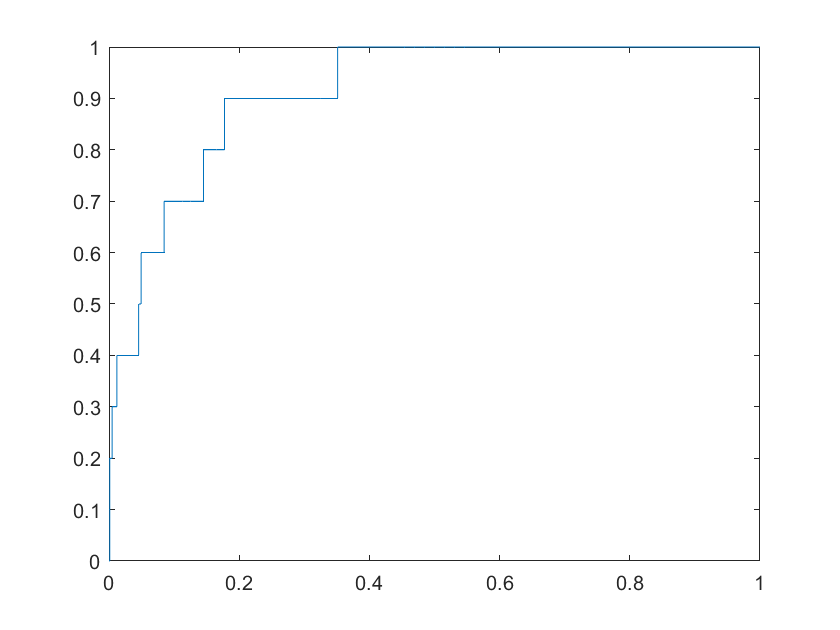

clf
plot(X,Y)

We get an AUC of **80.1% **for predicting** clinically significant MS**. This is surprisingly good! What happens if we model using **only** **murmur** grade?

[~,~,~,AUC1] = perfcurve(dataMdl.MSsig, dataMdl.Murmur_1_grade_ref_ny_T72, true)

AUC1 = 0.8630

[~,~,~,AUC2] = perfcurve(dataMdl.MSsig, dataMdl.Murmur_2_grade_ref_ny_T72, true)

AUC2 = 0.9233

[~,~,~,AUC3] = perfcurve(dataMdl.MSsig, dataMdl.Murmur_3_grade_ref_ny_T72, true)

AUC3 = 0.9234

[~,~,~,AUC4] = perfcurve(dataMdl.MSsig, dataMdl.Murmur_4_grade_ref_ny_T72, true)

AUC4 = 0.8739

[X,Y,~,AUC]  = perfcurve(dataMdl.MSsig, dataMdl.maxMeanMurGrade, true)

X =          0
    0.0021
    0.0053
    0.0127
    0.0233
    0.0445
    0.0646
    0.0996
    0.1367
    0.1774


Y =          0
    0.1000
    0.3000
    0.3000
    0.5000
    0.6000
    1.0000
    1.0000
    1.0000
    1.0000


AUC = 0.9703

[AUC1,AUC2,AUC3,AUC4,AUC]'   

ans =     0.8630
    0.9233
    0.9234
    0.8739
    0.9703


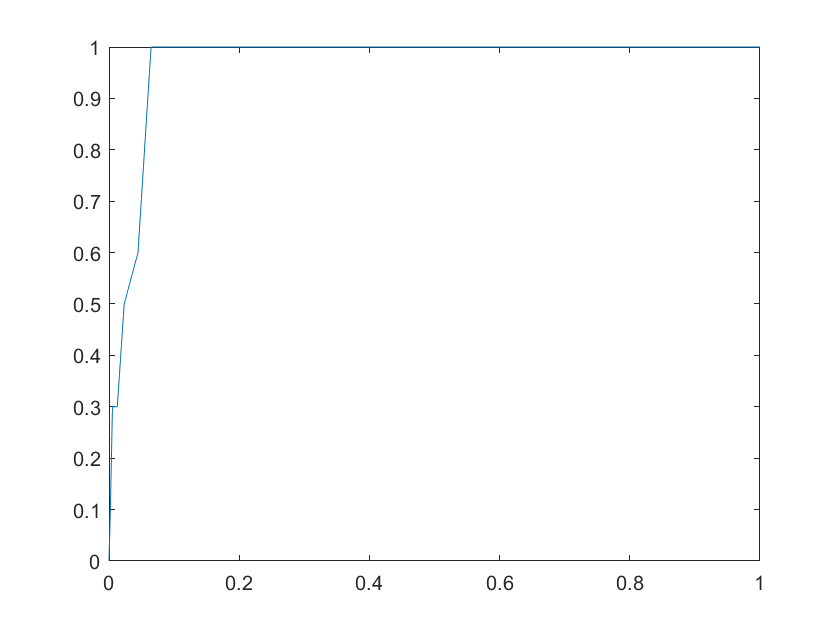

clf
plot(X,Y)

When we use only max murmur grade to predict AR, we get an AUC of **97.2%**. This is better than I thought it would be. Cleary, using the other covariates results in a much better model. Finally, lets try adding murmur grade to the **full model.**

formula = strcat('MSsig ~ AGE_T7 + SEX_T7 + HIGH_BLOOD_PRESSURE_T7 +',...
     'DYSPNEA_FAST_UPHILL_T7 + CHEST_PAIN_FAST_T7 + PULSESPIRO_T72 + maxMeanMurGrade')

formula = 'MSsig ~ AGE_T7 + SEX_T7 + HIGH_BLOOD_PRESSURE_T7 +DYSPNEA_FAST_UPHILL_T7 + CHEST_PAIN_FAST_T7 + PULSESPIRO_T72 + maxMeanMurGrade'

glm = fitglm(dataMdl,formula,'distr','binomial')

glm = Generalized linear regression model:
    logit(MSsig) ~ 1 + AGE_T7 + SEX_T7 + HIGH_BLOOD_PRESSURE_T7 + CHEST_PAIN_FAST_T7 + DYSPNEA_FAST_UPHILL_T7 + PULSESPIRO_T72 + maxMeanMurGrade
    Distribution = Binomial

Estimated Coefficients:
                                   Estimate       SE        tStat        pValue  
                                   ________    ________    ________    __________

    (Intercept)                      -25.84      6.3607     -4.0624    4.8562e-05
    AGE_T7                          0.16864    0.068085      2.4769      0.013253
    SEX_T7_1                       -0.14529     0.78682    -0.18466        0.8535
    HIGH_BLOOD_PRESSURE_T7_true     0.63034     0.78326     0.80477       0.42095
    CHEST_PAIN_FAST_T7_1            0.68236  


[X,Y,T,AUC] = perfcurve(dataMdl.MSsig, glm.predict, true)

X =          0
    0.0005
    0.0005
    0.0005
    0.0011
    0.0011
    0.0016
    0.0021
    0.0021
    0.0026


Y =          0
         0
    0.1000
    0.2000
    0.2000
    0.3000
    0.3000
    0.3000
    0.4000
    0.4000


T =     0.7106
    0.7106
    0.4176
    0.4016
    0.3973
    0.3370
    0.2993
    0.2882
    0.2881
    0.2405


AUC = 0.9868

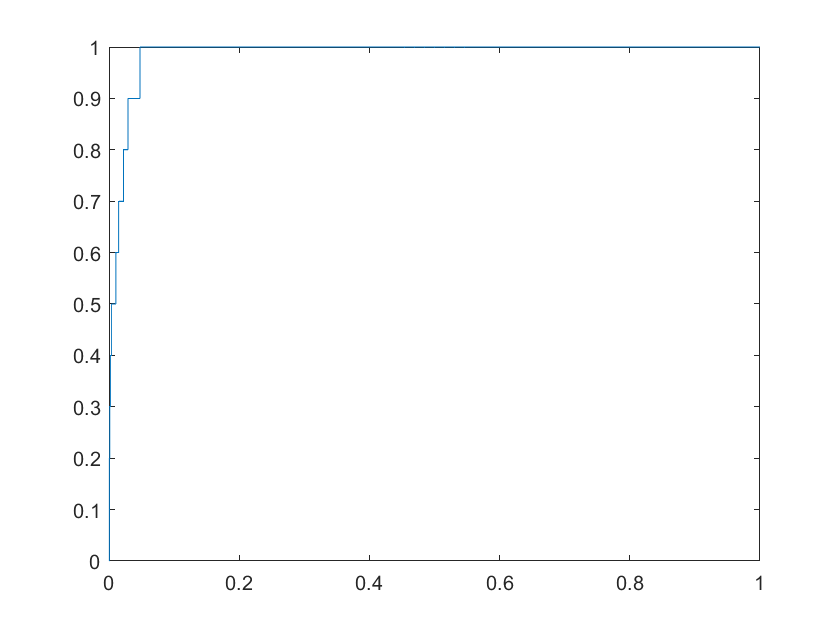

clf
plot(X,Y)

We get an AUC of **98.7%**, which is an increase of 1**.5%**. This is significant. Dyspnea, chest pain, 

formula = strcat('MSsig ~ AGE_T7 +',...
     '  PULSESPIRO_T72 + maxMeanMurGrade')

formula = 'MSsig ~ AGE_T7 +  PULSESPIRO_T72 + maxMeanMurGrade'

glm = fitglm(dataMdl,formula,'distr','binomial')

glm = Generalized linear regression model:
    logit(MSsig) ~ 1 + AGE_T7 + PULSESPIRO_T72 + maxMeanMurGrade
    Distribution = Binomial

Estimated Coefficients:
                       Estimate       SE        tStat       pValue  
                       ________    ________    _______    __________

    (Intercept)         -25.704      5.9814    -4.2973     1.729e-05
    AGE_T7              0.17005    0.065777     2.5853     0.0097285
    PULSESPIRO_T72     0.083128    0.033629     2.4719      0.013439
    maxMeanMurGrade       1.339     0.28796     4.6499    3.3215e-06


1898 observations, 1894 error degrees of freedom
Dispersion: 1
Chi^2-statistic vs. constant model: 61.5, p-value = 2.85e-13


[X,Y,T,AUC] = perfcurve(dataMdl.MSsig, glm.predict, true)

X =          0
    0.0005
    0.0005
    0.0005
    0.0011
    0.0011
    0.0016
    0.0021
    0.0021
    0.0026


Y =          0
         0
    0.1000
    0.2000
    0.2000
    0.3000
    0.3000
    0.3000
    0.4000
    0.4000


T =     0.6635
    0.6635
    0.4349
    0.4168
    0.3596
    0.3572
    0.3093
    0.2844
    0.2818
    0.2632


AUC = 0.9839

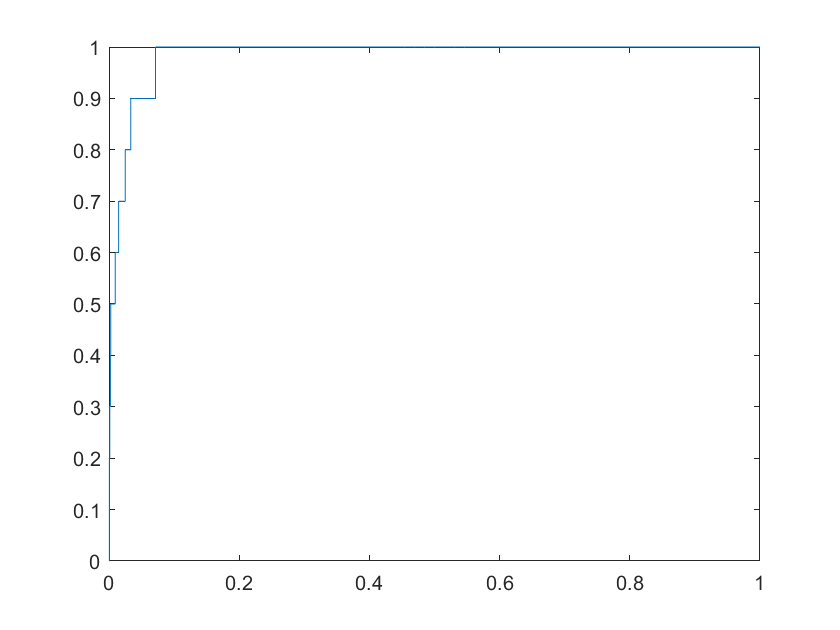

clf
plot(X,Y)

The AUC is now **98.4%. **The AUC when using recordings from only one area was** 94.9%, 98.15%, 98.2% **and** 97.4%, **so using maximum murmur grade was benificial. This is very exciting. Using only age, sex and maximum murmur grade we are able to predict AS presence with an AUC close to 100. In a paper published in 1988, sensitivity and specificity for detecting moderate to severe AS was only **83%** and **79%** respectively, which corresponds to an AUC of **81%**.

### conclusion:

Murmur grade is accurate for detecting even mild cases of AS. Using Sex and Age in a multivariate model achieves even greater accuracy. The implication of these results is that AS can be predicted with high accuracy at home using an app if we were to implement the murmur detection algorithm. This can allow assymptomatic patients to be detected much earlier, and can save doctors time.